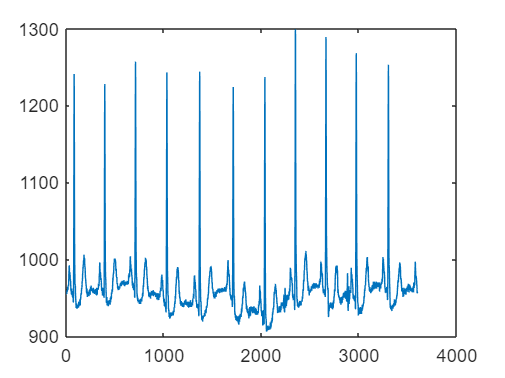

clear all
clc
close all
[filename, pathname] = uigetfile('*.dat', '101.dat');% only image Bitmap
if isequal(filename, 0) || isequal(pathname, 0)   
    disp('File input canceled.');  
   ECG_Data = [];  
else
fid=fopen(filename,'r');
end;
time=10;
f=fread(fid,2*360*time,'ubit12');
Orig_Sig=f(1:2:length(f));
plot(Orig_Sig)